# Integración por partes 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

La integración por partes es un método de integración extremadamente poderoso que solo se enfocará por completo una vez que lo apliques a la resolución de ecuaciones diferenciales. Por el momento, sin embargo, te permitirá resolver algunas integrales con las que la sustitución no ayuda. 

 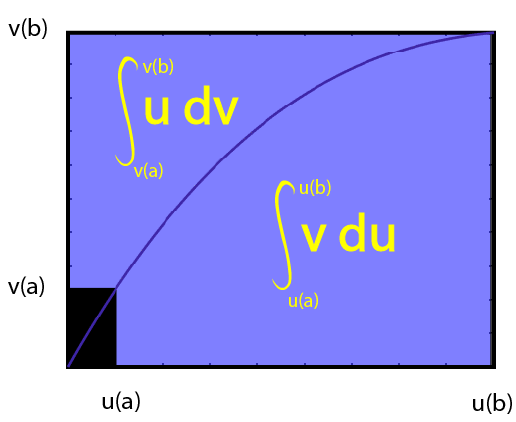

La integración por partes le permite subdividir su integrando en componentes integrados y diferenciados y recombinar esas piezas de maneras que puedan ser más fáciles de calcular. 

** Antes de comenzar: **

 Este script en vivo está diseñado para usarse con el código oculto. En la pestaña ** Ver ** de la tira de herramientas MATLAB, en la sección ** Ver **, seleccione ** Ocultar código **.  Alternativamente, seleccione ** Ocultar código ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [Rampa de entrada de MATLAB](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

##  Identificar componentes integrables y diferenciables 

Cuando hay un logaritmo natural en un integrando que no existe como parte de una sustitución, el único método exacto disponible es usar la integración por partes con el logaritmo natural como $u$ en la ecuación 


$$\int u(t)\cdot \frac{dv}{dt}\; dt = u(t)\cdot v(t) - \int v(t) \frac{du}{dt}\; dt. \;\;\;\;\;\;\; (\diamond)$$


  ** Consejo profesional **. La sintaxis de MATLAB es 7 `*t^(2/3)` para $7t^{2/3}$. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

###  Práctica de potencias y logaritmos 

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declarar variables simbólicas
    varOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
end
[myFun1,varChoice] = GenProbType(varOpts,3);  % genProbType está definido en Funciones auxiliares
% genProbType configura una variable y genera una función aleatoria

                                   % Run this section 

if ~exist("myFun1","var")
    disp("You must generate a power and logarithms practice problem before you can solve it.")
else
    myAnswer = r;     % Solución definida por el usuario, valor predeterminado r
    assume(varChoice>0)
    Check1(myFun1,varChoice,myAnswer);
end
                          % Run this section

###  Práctica de polinomios y cosenos, senos o exponenciales 

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declarar variables simbólicas
    varOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
end
    [myFun2,varChoice] = GenProbType(varOpts,2);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    
                                   % Run this section 

if ~exist("myFun2","var")
    disp("You must generate a polynomials and cosines, sines or exponentials practice problem before you can solve it.")
else
    myAnswer = r;     % Solución definida por el usuario, valor predeterminado r
    assume(varChoice>0)
    Check1(myFun2,varChoice,myAnswer);
end
                          % Run this section

###  Práctica de cosenos, senos y exponenciales 

if ~exist("varOpts","var")
    syms t r x z C                       %#ok<NASGU> % Declarar variables simbólicas
    varOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
end
    [myFun3,varChoice] = GenProbType(varOpts,4);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    
                                   % Run this section 

if ~exist("myFun3","var")
    disp("You must generate a cosines, sines, and exponentials practice problem before you can solve it.")
else
    myAnswer = r;     % Solución definida por el usuario, valor predeterminado r
    assume(varChoice>0)
    Check1(myFun3,varChoice,myAnswer);
end
                          % Run this section

##  Practique la integración aleatoria por integrales de partes 

  ** Pro-tip **. La sintaxis de MATLAB es 7 `*t^(2/3)` para $7t^{2/3}$. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

% Borrar variables que pueden reutilizarse en otras partes de este módulo.
clear errorCount totIPProbs totAttempts adjustcount lastFive myFun varChoice
syms t r x z C                       % Declarar variables simbólicas
varOpts = [t r x z];                 % Definir la lista de variables a utilizar en los problemas.
errorCount = 0;                      % Inicializar un recuento de errores
totIPProbs = 0;                    % Inicializar un recuento del total de problemas intentados
totAttempts = 0;                     % Inicializar un recuento del total de soluciones ofrecidas
adjustCount = 0;                     % Conservar los recuentos si el usuario vuelve a enviar una solución
lastFive = zeros(1,5);               % Inicializar una matriz para registrar los últimos cinco resultados de la solución
 
disp("Values initialized for Integration by Parts Practice.") 

% Compruebe si la sección anterior se ha ejecutado
% Si no, proporcione una advertencia. Si es así genera un problema.
if ~exist("totIPProbs","var")
    warning("You must initialize values before you can generate a problem.")
else
    [myFun,varChoice] = GenProbType(varOpts,1);  % genProbType está definido en Funciones auxiliares
    % genProbType configura una variable y genera una función aleatoria
    totIPProbs = totIPProbs+1;     % Aumentar el recuento total de problemas intentados.
end
                                   % Run this section 

myAnswer = r;     % Solución definida por el usuario, valor predeterminado r
totAttempts = totAttempts + 1;       % Recuento de actualizaciones del total de intentos de solución
[lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totIPProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive);
% resubmissionCheck is defined in Helper Functions
% resubmissionCheck records the attempt and provides appropriate feedback
                          % Run this section 

Una vez que haya completado suficiente práctica, realice un seguimiento de los resultados generales de su práctica aquí: 

 
AnalyzeResults(totIPProbs,errorCount,totAttempts,adjustCount,lastFive)

###  Aplicación de práctica 

Puede practicar en la aplicación Calculus Flashcards. Puede iniciar la aplicación haciendo clic en la imagen a continuación. Debe configurar el tipo de problema como "Integración por partes" en la sección Integrales. La aplicación se abrirá en una nueva ventana. 

[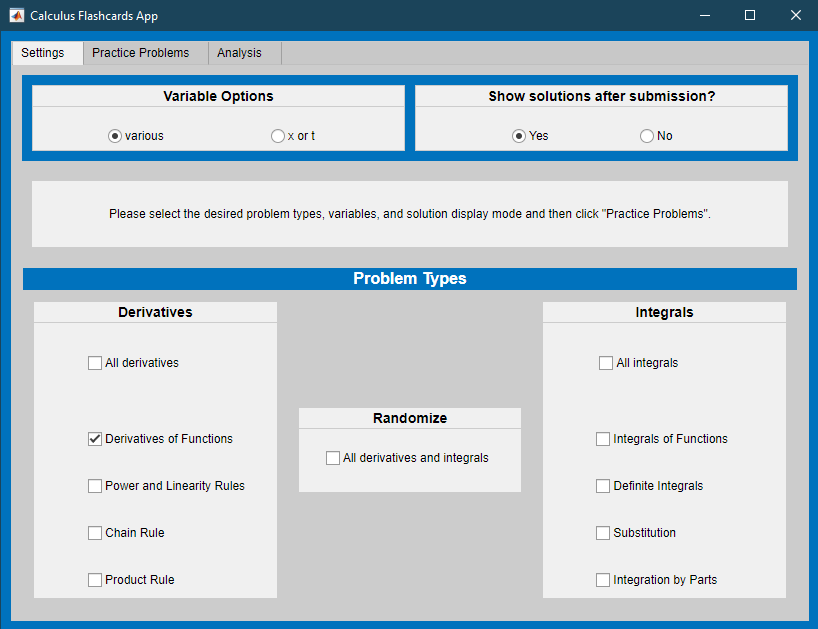](matlab: CalculusFlashcards)

 
run("CalculusFlashcards.mlapp")

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

Si desea ver los detalles del código, seleccione la pestaña ** Ver ** y cambie a ** Salida en línea **. Como alternativa, seleccione ** Salida en línea ** usando el ícono   en la parte superior derecha del panel Live Editor. 

**Generar funciones aleatorias para la práctica integral **

Generar funciones aleatorias 

function [myFunc,type] = GenFunDiff(bds,var,range)
syms f(t)                    % Crear una función simbólica f(t)
params = randi(bds,[1 4]);   % Elija aleatoriamente los valores de los parámetros
shift = randi([0 max(abs(bds))],1); % Elija aleatoriamente un turno que puede ser 0
sgns = randi([0 1],[1 3]);   % Elija aleatoriamente signos +/-
type = randi(range,1);


% Para facilitar la lectura, cree los parámetros a,b,c yd.
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, solo se usa como denominador
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^c*sin(b*t+d);
    case 2
        f(t) = a*t^c*cos(b*t+d);
    case 3
        f(t) = a*t^c*exp(b*t+d);
    case 4
        f(t) = a*t^b*log(c*t);
    case 5 
        f(t) = sin(b*t+d)*cos(c*t+a);
    case 6
        f(t) = a*sin(b*t+d)*exp(b/c*t+c*d);
    case 7
        f(t) = a*cos(b*t+d)*exp(b/c*t+c*d);
end
myFunc = f(var);
end 

Imprimir el problema que se ha creado 

function [myFun,varChoice] = GenProbType(varOpts,probType)
% genProbType configura una variable y genera una función aleatoria
%
% Entradas: varOpts es una matriz de posibles variables
% probType es una cadena que identifica el tipo de función
% Salidas: myFun es una función simbólica
% varChoice es la variable independiente
% probType es un número entero que rastrea el tipo de pregunta formulada
% [a, b] son ��los límites de la integral definida, si es necesario

% Seleccione aleatoriamente una variable del conjunto varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Utilice genFunDiff para generar funciones simples
% genFunDiff se define en Funciones auxiliares
% Las entradas a genFunDiff son la variable varChoice, un rango de valores
% entre los cuales seleccionar coeficientes y un valor que indica cuál Las advertencias
% ya se han impreso durante la generación del problema.
syms f(x) x
switch probType
    case 1 % Derivada por partes, general
        [f(x),~] = GenFunDiff([1 3],x,[1 7]);
    case 2 % Por partes, poli * cos/sin/exp
        [f(x),~] = GenFunDiff([1 3],x,[1 3]);
    case 3 % Por partes, poli*log
        [f(x),~] = GenFunDiff([1 3],x,[4 4]);
    case 4 % Por partes, cos/sin * cos/sin/exp
        [f(x),~] = GenFunDiff([1 3],x,[5 7]);
end
myFun = f(varChoice);
% Mostrar el problema integral
disp("Calculate the integral:")
displayFormula("F(varChoice) == int(myFun,varChoice)")
end 

Manejar envíos 

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;

    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);


elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
            disp("The "+sum(numSkipped)+" problems generated without attempts at solution " + ...
                "have been included in the count of errors.")
        else
            disp("The problem generated without an attempt at solution has been " + ...
                "included in the count of errors.")
        end
        [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
    end
else
    [lastFive,errorCount] = Check1(myFun,varChoice,myAnswer,errorCount,lastFive);
end
end 

Verificar soluciones 

function [lastFive,errorCount] = Check1(myFunc,myVar,myAnswer,varargin)
% check1 genera respuestas correctas diferenciando y actualiza
% errorCount y lastFive
%
% Entradas: myFunc es la función simbólica para diferenciar o integrar
% myVar es la variable independiente
% myAnswer es la función o número de prueba simbólica
% Entradas opcionales:
% errorCount es un seguimiento de enteros total de intentos incorrectos
% lastFive es un vector que rastrea los últimos cinco intentos
% Salida: correctAnswer es una función simbólica que es la
% solución a probType aplicada a myFunc(myVar) con bds
syms C
correctAnswer = int(myFunc,myVar)+C;
if ~isempty(varargin)
    errorCount = varargin{1};
    lastFive = varargin{2};
    lastFive(1:4) = lastFive(2:5);
else
    errorCount = 0;
    lastFive = zeros([1 5]);
end
disp("When simplified, this function is: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("That answer is correct.")
    lastFive(5) = 1;
elseif isAlways(diff(myAnswer,myVar)-myFunc==0,"Unknown","false")
    if diff(myAnswer,C) == 1
        disp("That answer is correct. Another possible form is:")
        disp(correctAnswer-C + "C")
        lastFive(5) = 1;
    else
        disp("You are missing a +C.")
        disp("The correct answer is:");
        correctAnswer %#ok<NOPRT>
        errorCount = errorCount + 1;
        lastFive(5) = 0;
    end
else
    disp("That is incorrect. The correct answer is:");
    correctAnswer %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Please try again with a new problem.")
    lastFive(5) = 0;
end
end 

Analizar resultados 

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analiceResults proporciona retroalimentación en el caso de un solo tipo de problema
% totProbs, errorCount, totAttempts y ajustaCount son números enteros
% lastFive es un vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % Si el usuario ha vuelto a enviar después de ver la solución, responda
    disp("Why are you resubmitting after you know the solution?")
    disp("Resubmissions are not included in your statistics.")
    if sum(adjustCount) > 1
        % If the user is repeatedly resubmitting, encourage them to use
        % this problem generator as intended by starting over
        disp("You have resubmitted " + sum(adjustCount) + " times.")
        disp("Please consider restarting the count using the `Initialize Values' button.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, %i were correct.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, one was correct.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
            "Of the last five, none were correct.",overallRight,totProbs);
    end
else
    % Si se han intentado menos de 5 problemas, fomente la perseverancia.
    str = compose("The overall success rate is %.1f%% on %i total problems \n\n" + ...
        "Please do at least five problems.",overallRight,totProbs);
end
disp(str)
end